% Design A 2 Stage Rocket (in mathematical terms)

% Source for propellent (fuel)
% https://www.funkystuff.org/rockets-and-their-propellants/

% DESCRIPTION OF ROCKET DESIGN 
% 
% I chose a solid fuel for both rocket stages. It is more convenient to
% have solid fuel than to maintian liquid fuel. I specifically chose the
% type of fuel to be HTPB Solid. This fuel is a good solid fuel source for
% a variety of rockets according to the website above. This wide
% applicability made it my top choice. 
% The fuel has a specific impulse of 275 with a general range of 260-280, which
% is standard for rocketry (around 300). The first stage held 80% of the rocket propellant mass
% while the second stage held 20%. This is because it takes a lot more propellant to 
% launch the rocket from Earth's surface at zero velocity than it does to maintain flight
% after the first stage burns out. The 80/20 rule seemed like a sufficient ratio to use,
% and a similar ratio to two stage rockets in general. The amount of structural
% mass for each stage had the same ratio. For the total mass (based on these ratios and total mass), 
% the payload took 23 percent leaving 9 percent to structural mass and 60 percent to propellant mass.
% The thrust to weight ratio was 1.5 for the first stage, as a ratio significantly greater than 1 is crucial 
% for getting off the ground. However, 1.5 seemed realistic for a solid fuel instead of a higher number.
% The thrust to weight ratio of the second stage was just 1.0, as the rocket was already in flight and had momentum, 
% but needed to maintain itself.
% With these mass ratios assigned and the thrust to weight ratio assigned, the thrust for
% the first stage is 73575 N and 9810 N for the second stage. Therefore,
% the mass flow rate before the first stage dropped off was 27.27, but then
% changes to 3.63 once the first stage leaves the rocket. The burn times
% are dependent on allocated propellent mass and the mass flow rate. Thus,
% the burn time for stage 1 was 100 seconds and for stage 2 after stage 1 was
% 187 seconds. The structural and payload coefficients are also derived from how
% mass was allocated throughout the rocket. 
% 

% Stat break down
% Fuel: HTPB Solid (solid fuel)
% Isp: 275
% m_total first stage (no payload): 3850 kg
% m_total second stage (no payload): 1150 kg
% m_p first stage: 2720 kg
% m_p second stage: 680 kg
% m_s first stage: 360 kg
% m_s second stage: 90 kg
% Thrust first stage: 73575 N
% Thrust second stage: 9810 N
% mass flow rate first stage: 27.27 kg/s
% mass flow rate second stage: 3.63 kg/s
% burn time first stage: 100 s
% burn time second stage: 187 s
% Structural coefficient: 0.1169
% Payload coefficient: 0.2897


% CODE FOR PLOTS AND DELTA V
% 2 stage rocket

% Gravity of Earth
g_0 = 9.81;
% Isp 
Isp = 275;


%Thrust to weight ratio for stage 1
T2W_1 = 1.5;
%Thrust to weight ratio for stage 1
T2W_2 = 1.0;

% Payload mass
m_pay = 150 + 0.2*5000;
% mass of each stage
m_1 = 3850; % for stage 1
m_2 = 1150; % for stage 2

%Propellent mass and structure mass deligated for stages 1 and 2
m_p = (0.68*5000); 
m_p1 = 0.8*m_p;
m_p2 = 0.2*m_p;
m_s = (0.09*5000); 

% Total mass of the rocket
tot_m = m_pay + m_p + m_s;

% weight and thrust
W_1 = tot_m*g_0 ;
W_2 = 0.2*W_1;
T_1 = T2W_1*W_1;
T_2 = T2W_2*W_2;

% lambda and epsilon ratios
lambda = m_pay/(m_p + m_s);
epsilon = m_s/(m_s + m_p);
R = ((1 + lambda)/(epsilon + lambda));

% ensure that epsilon is reasonable (no lower than 0.05)
if epsilon < 0.05
    fprintf("Epsilon too small: ");
    disp(epsilon);
end

% Changes in mass for each rocket stage based on the thrust (dm)
dm1 = T_1/(Isp*g_0);
dm2 = T_2/(Isp*g_0);

% Burn times
t_b1 = round(m_p1/dm1); % burn time of stage 1
t_b2 = round(m_p2/dm2); % burn time of stage 2
t_bt = t_b1 + t_b2; % total burn time of rocket

% make iteration lengths for each  burn time (iterate for every 0.1 seconds not
% every second)
tb1_i = t_b1/0.1;
tb2_i = t_b2/0.1;

% total time that will be plotted
t = t_b1 + t_b2 + 700;

% modify for iteration
dt = 0.1;
t_i = 10*t;

% Calculating m for stages 1 and 2 using thrust

m = zeros(t_i, 1); %Initialize array of mass over time
m(1) = 5000; % Initial mass of rocket right at launch

for i = 2:(t_i)
    if i < 1000
        m(i) = m(1) - dm1*i*0.1;
    end
    if i == (1000) % This is the time right after the first stage of the rocket burns up
        m(i) = 1150; % Total mass of stage 2 before burning
    end
    if i > 1000 && i <= (t_bt*10) % t_bt represents the total burn time. 
        % It is multiplied by ten here cause each iteration is 0.1 seconds
        % instead of 1 second.
        m(i) = 1150 - dm2*(i-1000)*0.1;
    end
    if i > (t_bt*10) % at this point, the mass of the rocket is not changing 
        % since the time is greater than the total burn time of the rocket
        m(i) = m(t_bt*10);
    end

end


% Then calculate acceleration

% Initializing acceleration and drag force through flight time
a = zeros(t_i, 1);
drag = zeros(t_i,1);
for j = 1:t_i
    if j < 1000
        a(j) = T_1/m(j) - g_0/g_0 - drag(j)/m(j);  % using T (force) = m*a or Newton's Second Law
    end
    if j == 1000
        a(j) = a(j-1);
    end
    if j > 1000 && j < (t_bt*10)
        a(j) = T_2/m(j) - g_0/g_0 - drag(j)/m(j);
    end
    if j > (t_bt*10)
        a(j) = - g_0/g_0 - drag(j)/m(j); % assuming gravity and drag force still have an effect on the rocket 
        % after burn time (likely does not). The acceleration here can
        % easily be changed to zero to modify the assumption.
    end

end


% Values needed to calculate drag force (used in acceleration calculations)
p = 1.225; % air density in kg/m^3
scale_height = 10000;
A = 0.15; % cross sectional area m^2
c_d = 0.75; % coefficient of drag
y = 1000;

%Calculating velocity and drag force

% Initializing array of velocities over flight time
v = zeros(t_i, 1);

for k = 2:(t_i)
     v(k) = v(k-1) + a(k)*dt; % using kinematic equation for velocity
     drag(k) = 0.5*p*exp(-y/scale_height)*c_d*A*(v(k)); % using drag equation
end

% Getting delta_v using the rocket equation (excluding gravity and drag
% forces)
delta_v = g_0*Isp*log(R);

% find altitude

% initializing altitude of rocket over time (starting at zero)
alt = zeros(t_i,1);

for pos = 2:(t_i)
    alt(pos) = alt(pos-1) + v(pos-1)*dt + 0.5*a(pos)*(dt^2); % using kinematic equations
end
% Now it is time to plot acceleration, velocity, and altitude :

X = linspace(0,t,t_i); % array of time in increments of t_i

%Plot mass
fprintf("Plot of rocket mass: ");

Plot of rocket mass: 

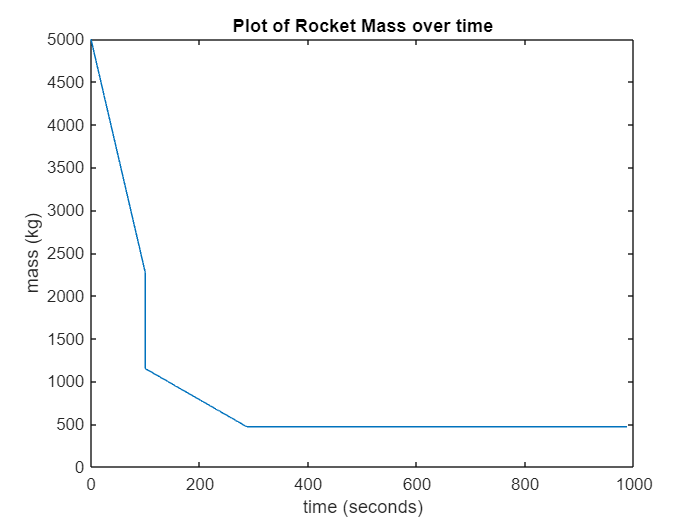

figure;
plot(X,m');
title ("Plot of Rocket Mass over time");
xlabel('time (seconds)');
ylabel('mass (kg)');


%Plot altitudes
fprintf("Plot of rocket altitude: ");

Plot of rocket altitude: 

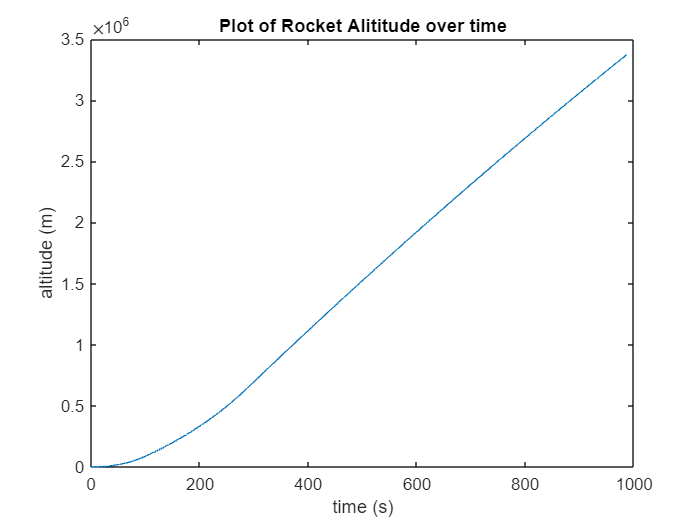

figure;
plot(X,alt');
title ("Plot of Rocket Alititude over time");
xlabel('time (s)');
ylabel('altitude (m)');


%Plot velocities
fprintf("Plot of rocket velocity: ");

Plot of rocket velocity: 

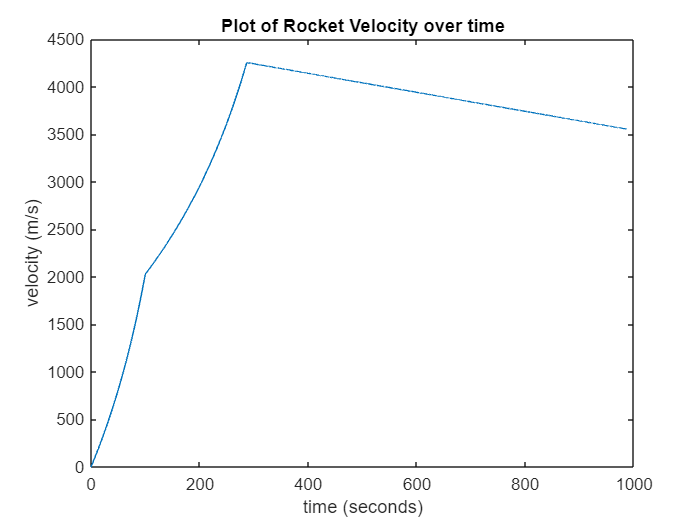

figure;
plot(X,v');
title ("Plot of Rocket Velocity over time");
xlabel('time (seconds)');
ylabel('velocity (m/s)');

%Plot accelerations (g's)
fprintf("Plot of first stage G's: ");

Plot of first stage G's: 

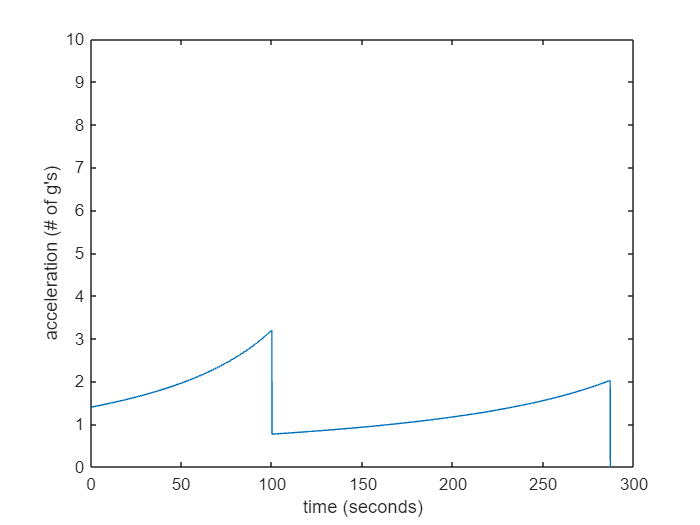

figure;
plot(X,(a/9.81)');
xlim([0,300]);
ylim([0,10]);
xlabel('time (seconds)');
ylabel('acceleration (# of g''s)');

%Display delta v's
fprintf("Here is the delta v for the rocket: ");

Here is the delta v for the rocket: 

disp(delta_v);

   3.0739e+03



fprintf(" m/s");

 m/s